# Optimal Borrowing Choice Firm Maximization

[**Back to Fan's Math for Economist Table of Content**](https://fanwangecon.github.io/Math4Econ/)

## Model Components and Maximization Problem

Assume that the firm has fixed free labor, but can choose capital input. At the start of a period, a firm rents capital inputs and combines capital with labor to produce. At the end of the period, the firm sells its output and pays interest rates based on how much capital it rented (no wage costs). Profit is denoted by π, period interest rate is $r$, the price of output is $p$, the firm makes $y$ units of output, and the production function is Cobb-Douglas: $A\cdot K^{\alpha}\cdot L^{0.5}$

- **Profit: **$\Pi =  p\cdot A\cdot K^{\alpha}\cdot L^{0.5}-r\cdot K$

**Profit Maximization:**

- 
$$\max_{K} \left( p\cdot A\cdot K^{\alpha}\cdot L^{0.5}-r\cdot K \right)$$


## Finding Optimal Choices--Brute Force Grid

We can visualize the solution here like we do for the household savings problem

clear all;
alpha=0.25;
A=1;
r=1.05;
p=1;
L=2;
choice_grid_count=100;
capital_grid=linspace(0, 1,choice_grid_count);
profit_at_capitalgrid=p*A*(capital_grid.^alpha)*(L^0.5)-(r*capital_grid);
[max_profit, max_profit_index]=max(profit_at_capitalgrid);
max_profit

max_profit = 0.7379

max_profit_index

max_profit_index = 24

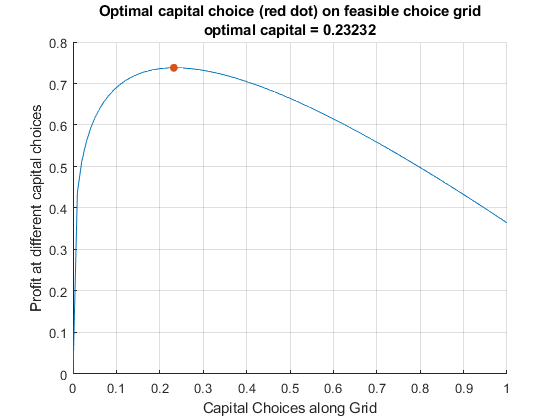

optimal_capital_choice = capital_grid(max_profit_index);
figure();
hold on;
plot(capital_grid, profit_at_capitalgrid);
scatter(optimal_capital_choice, max_profit, 'filled');
xlabel('Capital Choices along Grid');
ylabel('Profit at different capital choices');
title({'Optimal capital choice (red dot) on feasible choice grid';...
 ['optimal capital = ', num2str(optimal_capital_choice)]});
grid on;

## Analytical Solution

You can use the symbolic toolbox to take derivative and find root:

syms r p alpha L K A
f_pi = p*A*K^(alpha)*L^0.5 - r*K

$$f\_pi = A\,K^{\alpha }\,\sqrt{L}\,p-K\,r$$

dPI_dK = diff(f_pi, K)

$$dPI\_dK = A\,K^{\alpha -1}\,\sqrt{L}\,\alpha \,p-r$$

K_opti = solve(dPI_dK == 0, K, 'REAL',true)

$$K\_opti = {\left(\frac{r}{A\,\sqrt{L}\,\alpha \,p}\right)}^{\frac{1}{\alpha -1}}$$

## Demand Curve For Capital

With the optimal capital choice as a function of interest rate, we can plot out the demand for capital.

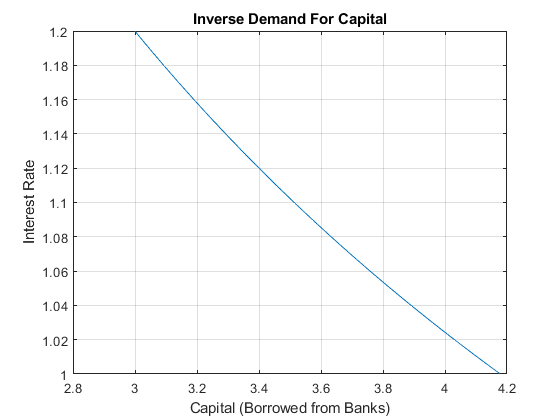

p=1.15; %From the question.
L=2; %From the question.
A=3; %You can pick a random number.
alpha=0.45; %You can pick a random number.
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Inverse Demand For Capital'});
grid on;

## Demand and Supply Intersection

Combining the Firm's problem here, and the household's problem from the other file, we have the equilibrium result. 

Note that you should adjust your interest rate range so that you can see the intersection. For the problem here, there exists an interest rate that clears the market for capital.

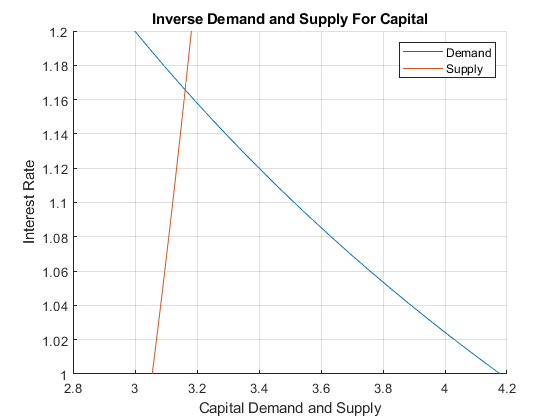

z=10;% from household problem
beta=0.80; % from household problem
p=1.15; %From the question.
L=2; %From the question.
A=3; %You can pick a random number.
alpha=0.45; %You can pick a random number.
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
Demand = (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
Supply = (z*beta*(1+r)-(z/2))./((1+r)*(1+beta));
% Plot
figure();
hold on;
plot(Demand,r);
plot(Supply,r);
xlabel('Capital Demand and Supply');
ylabel('Interest Rate');
title({'Inverse Demand and Supply For Capital'});
legend({'Demand', 'Supply'});
grid on;